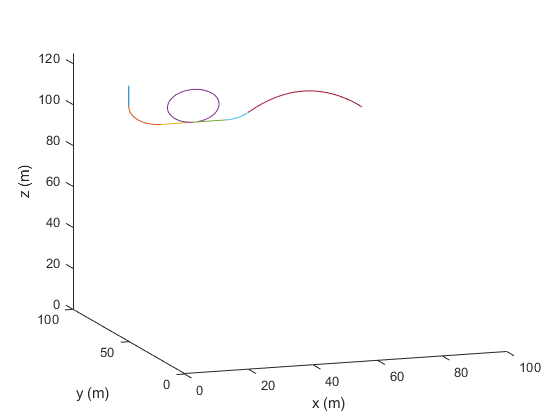

[x1, y1, z1, vel1, Gx1, Gy1, Gz1] = section1(0,50,125);
plot3(x1,y1,z1)
xlabel("x (m)")
ylabel("y (m)")
zlabel("z (m)")
xlim([0 100])
ylim([0 100])
zlim([0 125])
[x2, y2, z2, vel2, Gx2, Gy2, Gz2] = section2(x1(end),y1(end),z1(end));
hold on
plot3(x2,y2,z2)
[x3, y3, z3, vel3, Gx3, Gy3, Gz3] = section3(x2(end),y2(end),z2(end),10);
plot3(x3,y3,z3)
hold on
[x4,y4,z4,vel4,Gx4,Gy4,Gz4] = loopPath(x3(end),y3(end),z3(end),8,1);
plot3(x4,y4,z4)
[x5, y5, z5, vel5, Gx5, Gy5, Gz5] = section3(x4(end),y4(end),z4(end),10);
plot3(x5,y5,z5)
[x6, y6, z6, vel6, Gx6, Gy6, Gz6] = launch(x5(end),y5(end),z5(end));
plot3(x6,y6,z6)
parabolicPos = [x6(end),y6(end),z6(end)];
parabolicVel = [vel6(end)*sqrt(2)/2,0,vel6(end)*sqrt(2)/2];
[x7, y7, z7, vel7, Gx7, Gy7, Gz7, vf] = Parabola(parabolicVel,parabolicPos);
plot3(x7,y7,z7)
hold off

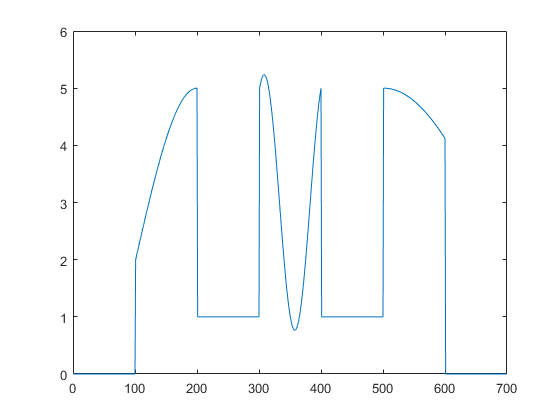

plot([Gz1 Gz2 Gz3 Gz4 Gz5 Gz6 Gz7])

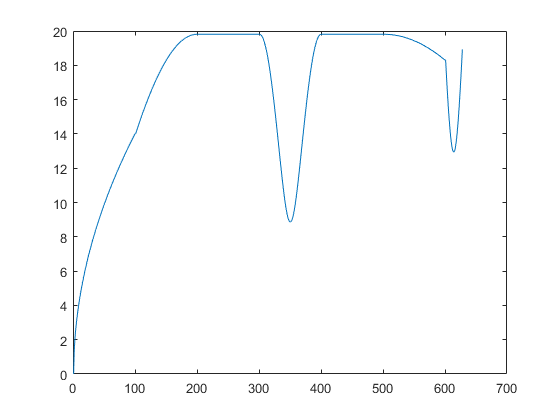

plot([vel1 vel2 vel3 vel4 vel5 vel6 vel7])

function [x, y, z, vel, Gx, Gy, Gz] = section1(xI,yI,zI)
%     theta = linspace(pi/2,0,100);
%     radius = 10;
%     g = 9.81;
%     x = radius.*cos(theta) + xI;
%     y = theta.*0 + yI;
%     z = radius.*sin(theta) + zI - radius;
%     vel = sqrt(2 .* g .* (zI - z));
%     Gz = -((vel.^2)./(g * radius)) + sin(theta);
%     Gx = theta .* 0;
%     Gy = theta .* 0;
    t = linspace(0,10,100);
    g = 9.81;
    x = t.*0 + xI;
    y = t.*0 + yI;
    z = -t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0;
    Gx = t .* 0;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section2(xI,yI,zI)
    % circular section, G's occur perpendicular to cart, vert -> flat
    theta = linspace(pi,3*pi/2,100);
    radius = 10;
    g = 9.81;
    x = radius.*cos(theta) + radius;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = theta .* 0;
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section3(xI,yI,zI,L)
    % linear section, 1G downwards, propogates in the x direction 
    t = linspace(0,L,100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + 1;
    Gx = t .* 0;
    Gy = t .* 0;
end
function [x,y,z,V,Gx,Gy,Gz] = loopPath(xI,yI,zI,r,prop)
    %% Setup
    % Note, this currently only calculated velocity correctly
    % if the path is one full loop. I need to add the calculations
    % for the velocity vector for a partial loop.
    h0 = 125; % [m] initial height
    m = 100;  % [kg] particle mass
    g = 9.81; % [m/s^2] gravity
    t = linspace(-pi/2,(prop.*2.*pi)-pi./2,100);
    %% calculating positions
    x = xI + r.*cos(t);
    z = zI + r + r.*sin(t);
    y = yI + 0.*t;         % If you change t to be multiplied by a nonzero number it becomes a helix
    %% velocity and G force calculations
    V = t.*0 + sqrt(2*g*(h0-z));
    N = m*((cos(t)*g)+((V.^2)/r));
    Gz = t.*0 + N/(m*g);
    Gx = t.*0;
    Gy = t.*0;
    %% output
end
function [x, y, z, vel, Gx, Gy, Gz] = launch(xI,yI,zI)
    % circular section, creates platform for parabolic section
    theta = linspace(3*pi/2,7*pi/4,100);
    radius = 10;
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = theta .* 0;
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz, vf] = Parabola(v0,pos0)
    %% Setup of variables and vectors
    t = linspace(0,10,100);
    g = 9.81;
    x = ones(1,length(t)).*4200; % filling with large values
    y = ones(1,length(t)).*4200; % to be trimmed later
    z = ones(1,length(t)).*4200;
    x(1) = pos0(1);
    y(1) = pos0(2);
    z(1) = pos0(3);
    i = 2;
    %% Calculating path with kinematics
    while i <= length(t)
        x(i) = (v0(1)*t(i))+x(1);
        y(i) = (v0(2)*t(i))+y(1);
        z(i) = ((v0(3)*t(i))-(0.5*g*t(i)*t(i)))+z(1);
        if z(i) <= z(1)
            i = length(t);
        end
        i = i + 1;
    end
    %% Trimming position vectors
    x = x(x ~= 4200);   % output, [meters]
    y = y(y ~= 4200);   % output, [meters]
    z = z(z ~= 4200);   % output, [meters]
    vel = sqrt(2*g.*(125-z));
    Gz = t .* 0;
    Gx = t .* 0;
    Gy = t .* 0;
    % z(end) = z(1);
    vf = [v0(1) v0(2) -v0(3)];  % output, [m/s]
end